# Project: Radar Target Generation and Detection

## FMCW Waveform Design

Using the given system requirements, design a FMCW waveform. Find its Bandwidth (B), chirp time (Tchirp) and slope of the chirp.

#### Radar system requiremetns

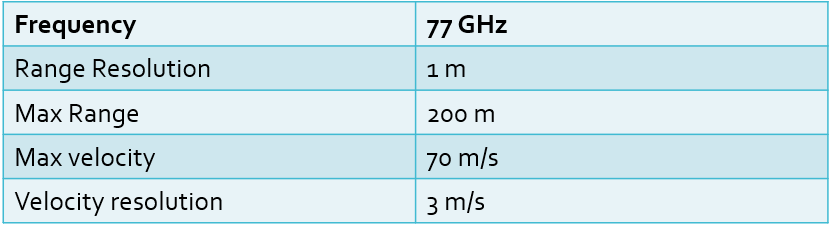

The sweep bandwidth can be determined according to the range resolution and the sweep slope is calculated using both sweep bandwidth and sweep time.

                            
$$B_{sweep} = c / (2*RangeResolution)$$


The sweep time can be computed based on the time needed for the signal  to travel the unambiguous maximum range. In general, for an FMCW radar  system, the sweep time should be at least 5 to 6 times the round trip  time.

                            
$$T_{chirp}=5.5*2*R_{max}/c$$


Giving the slope of the chirp signal,

                            
$$slope = B_{sweep}/T_{chirp}$$


#### Radar Specifications

% Operationg carrier frequency of the radar
fc = 77e9;  % 77 GHz

% range resolution
range_res = 1.0;  % m

% maximum range
Rmax = 200.0;    % m

% maximum velocity
Vmax = 100.0;    % m/s

% speed of light
c = 3e8;    % m/s

#### user defined inital range and velocity of the target

R0 = 100.0 % a value between 0 and 200

R0 = 100

V0 = 20.0  % a value between -70 and +70

V0 = 20

## Target generation and detection

#### FMCW Waveform Generation

% calculate sweep Bandwidth
Bsweep = c / 2 * range_res

Bsweep = 150000000


% calculate chirp time
factor = 5.5;   % a factor between 5 and 6
Tchirp = factor * 2 * Rmax / c

Tchirp = 7.3333e-06


% calculate slope
slope = Bsweep / Tchirp

slope = 2.0455e+13


% The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
% for Doppler Estimation
Nd = 128; % #of doppler cells OR #of sent periods % number of chirps

% The number of samples on each chirp. 
Nr = 1024;    %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t = linspace(0, Nd*Tchirp, Nr*Nd);    %total time for samples

%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx = zeros(1,length(t)); %transmitted signal
Rx = zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t = zeros(1,length(t));
td = zeros(1,length(t));


#### Signal generation and Moving Target simulation

% Running the radar scenario over the time. 

for i=1:length(t)         
    
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = R0 + V0 * t(i);
    td(i) = 2* r_t(i) / c;
    
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2*pi*(fc*t(i) + slope*(t(i)^2)/2));
    Rx (i)  =cos(2*pi*(fc*(t(i) - td(i)) + slope*((t(i) - td(i))^2)/2));
    
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i) .* Rx (i);
    
end


#### RANGE MEASUREMENT

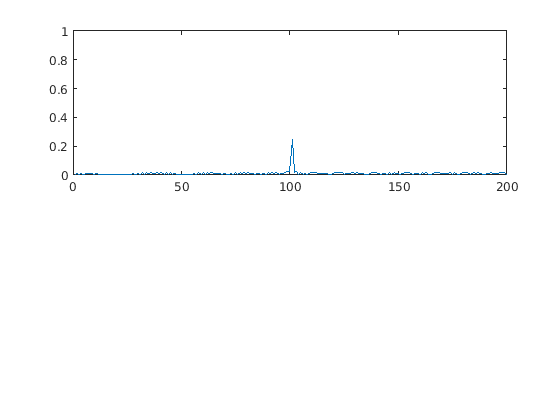

% *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.

Mix = reshape(Mix,[Nr, Nd]);

% *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.

y_fft = fft(Mix,Nr);
y_ft_norm = y_fft ./ Nr;

% *%TODO* :
% Take the absolute value of FFT output
y_ft_norm = abs(y_ft_norm);

% *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
y_fft_final = y_ft_norm(1:Nr/2);

%plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

% *%TODO* :
% plot FFT output 
plot(y_fft_final)
axis ([0 200 0 1]);

#### RANGE DOPPLER RESPONSE

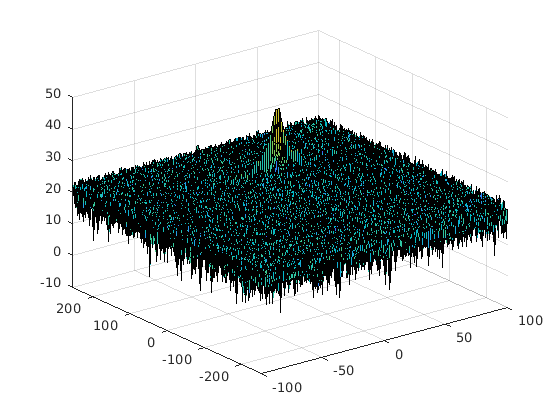

% The 2D FFT implementation is already provided here. This will run a 2DFFT
% on the mixed signal (beat signal) output and generate a range doppler
% map.You will implement CFAR on the generated RDM


% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM);

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

#### CFAR implementation

- define number of Training and Guard cells. The selected number is a trade off between computational complexity and performance. Numbers figured out experimentaly.

-  define threshold value. Value selected experimentaly and noise statistics observation

- For each possible CUT cell slide a 2D window. Possible CUT cells are those for which the sliding window fits within the boundaries of the RDM matrix.

- Average the values of the training cells. Appropriately convert values from logarithmic scale to linear and vica versa.

- Compare the average value to CUT value. Assign to CUT cell 1 if its value exceeds the average value plus a factor, else assign zero.

- Assigne zero value to the unthresholded cells.

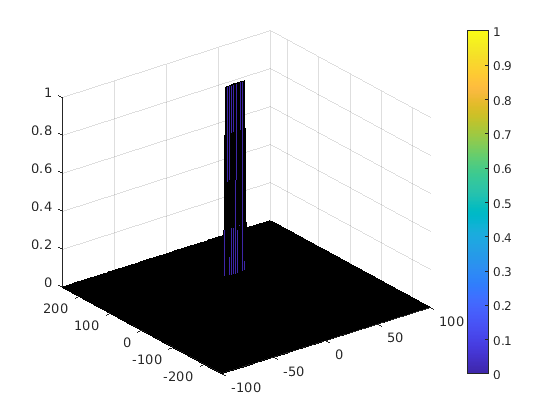

%Slide Window through the complete Range Doppler Map

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr = 10;
Td = 10;

% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr = 4;
Gd = 4;

% *%TODO* :
% offset the threshold by SNR value in dB
offset = 1.5;
% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells

%noise_level = zeros(1,1);


% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.

% Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
% CFAR

TGr = Tr + Gr;
TGd = Td + Gd;

result = zeros(size(RDM,1), size(RDM,2));

for i = TGr + 1 : size(RDM,1) - (TGr)
    for j = TGd + 1 : size(RDM,2) - (TGd)
        
        A = RDM((i-TGr):(i+TGr), (j-TGd):(j+TGd));
        A = db2pow(A);
        
        A((Tr+1):(Tr + 2*Gr +1), (Td+1):(Td + 2*Gd +1)) = 0.0;
        
        Asum = sum(A,'all');
        noise_level = Asum / (size(A,1)*size(A,2) - (2*Gr+1)*(2*Gd+1));
        noise_level = pow2db(noise_level) + factor;
        
        if RDM(i,j) > noise_level
            result(i,j) = 1;
        end
    end
end

% *%TODO* :
% The process above will generate a thresholded block, which is smaller 
%than the Range Doppler Map as the CUT cannot be located at the edges of
%matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 
 

% *%TODO* :
%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure('Name','CA-CFAR Filtered RDM')
figure,surf(doppler_axis,range_axis,result);
colorbar;